# Exam 2018

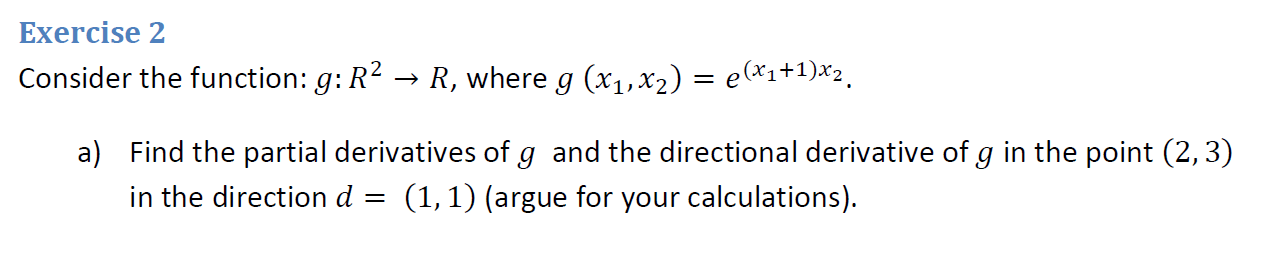

Gradiant of f is defined as : $\nabla f\left(x\right)=\left\lbrack \begin{array}{c}
\frac{\partial f}{\partial {\;x}_1 }\\
\frac{\partial f}{\partial {\;x}_2 }\\
\ldotp \ldotp \ldotp \\
\frac{\partial f}{\partial {\;x}_n }
\end{array}\right\rbrack \;$   First derivative-row vector is defined as : $D\;f\left(x\right)={\left(\nabla f\left(x\right)\right)}^T =\left\lbrack \begin{array}{cccc}
\frac{\partial f}{\partial {\;x}_1 } & \frac{\partial f}{\partial {\;x}_2 } & \ldotp \ldotp \ldotp  & \frac{\partial f}{\partial {\;x}_n }
\end{array}\right\rbrack$

We parcial differiance first for x1, then x2 $\nabla f\left(x\right)$

syms x1 x2
g = exp(1)^((x1+1)*x2);
gradiant_g = gradient(g, [x1,x2]);
d_gradiant_g = transpose(gradiant_g)

$$d\_gradiant\_g = \left(\begin{array}{cc} {\left(\frac{3060513257434037}{1125899906842624}\right)}^{x_{2}\,\left(x_{1}+1\right)}\,x_{2}\,\log\left(\frac{3060513257434037}{1125899906842624}\right) & {\left(\frac{3060513257434037}{1125899906842624}\right)}^{x_{2}\,\left(x_{1}+1\right)}\,\log\left(\frac{3060513257434037}{1125899906842624}\right)\,\left(x_{1}+1\right) \end{array}\right)$$

The can then calculate thte direction derivative as 


$${\frac{\partial f}{\partial d}\left(x\right)=\;\left(\nabla f\left(x\right)\right)}^T *d$$


We can then obtian the directional derevative : ${\left(\nabla f\left(x\right)\right)}^T *d$

d = [1, 1];
directional_derivative = d_gradiant_g*transpose(d)

$$directional\_derivative = {\left(\frac{3060513257434037}{1125899906842624}\right)}^{x_{2}\,\left(x_{1}+1\right)}\,\log\left(\frac{3060513257434037}{1125899906842624}\right)\,\left(x_{1}+1\right)+{\left(\frac{3060513257434037}{1125899906842624}\right)}^{x_{2}\,\left(x_{1}+1\right)}\,x_{2}\,\log\left(\frac{3060513257434037}{1125899906842624}\right)$$

point = [2,3];
% direction in the point [2,3] :
point_direction = exp(1)^((2+1)*3)

point_direction = 8.1031e+03

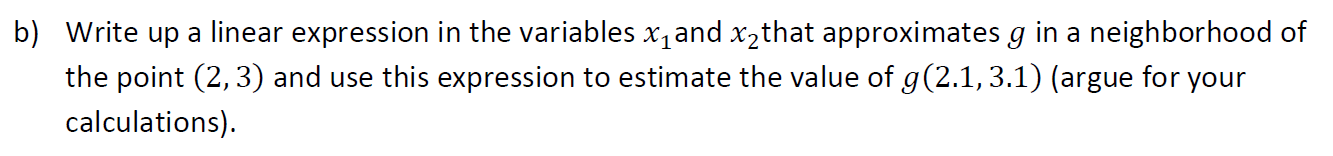

% GGGGGGGGGGGGGGGGGGGGGGGGGGGGGGGGGGGGGGGGGGGGGGG

We will use the Lagrange multiplier for the problem


$$\nabla f\left(x\right)+\lambda *\nabla h\left(x\right)=0$$
 

We can solve the follwing problem by solving 3 linequeations with 3 uknowns

clearvars
syms x1 x2
f = (x1-1)^2 + x2^2;
gradiant_f = gradient(f, [x1,x2]);

clear x1 x2
syms x1 x2 lambda
h = (x1^2)/9 + (x2^2)/4 - 1 

$$h = \frac{{x_{1}}^{2}}{9}+\frac{{x_{2}}^{2}}{4}-1$$

gradiant_h = gradient(h, [x1,x2])

$$gradiant\_h = \left(\begin{array}{c} \frac{2\,x_{1}}{9}\\ \frac{x_{2}}{2} \end{array}\right)$$

% Lagrange multiplier
Lagrange_multiplier = gradiant_f + lambda* gradiant_h == 0

$$Lagrange\_multiplier = \left(\begin{array}{c} 2\,x_{1}+\frac{2\,\lambda \,x_{1}}{9}-2=0\\ 2\,x_{2}+\frac{\lambda \,x_{2}}{2}=0 \end{array}\right)$$

% we now have 2 equation and 3 unknowns
% we can use the fuction h = 0 as the last one:
equation1 = Lagrange_multiplier(1)

$$equation1 = 2\,x_{1}+\frac{2\,\lambda \,x_{1}}{9}-2=0$$

equation2 = Lagrange_multiplier(2)

$$equation2 = 2\,x_{2}+\frac{\lambda \,x_{2}}{2}=0$$

equation3 = (x1^2)/9 + (x2^2)/4 - 1   == 0

$$equation3 = \frac{{x_{1}}^{2}}{9}+\frac{{x_{2}}^{2}}{4}-1=0$$


[x1,x2,lambda] = solve([equation1, equation2, equation3], [x1,x2, lambda]);
x1 = double(x1)

x1 =     3.0000
   -3.0000
    1.8000
    1.8000


x2 = double(x2)

x2 =          0
         0
   -1.6000
    1.6000


lambda = double(lambda)

lambda =     -6
   -12
    -4
    -4


% candidate coordinates 
s1 = [x1(1), x2(1)];
s2 = [x1(2), x2(2)];
s3 = [x1(3), x2(3)];
s4 = [x1(4), x2(4)];

% Solutions
%(x1-1)^2 + x2^2;
f1 = (s1(1)-1)^2 + s1(2)^2

f1 = 4

f2 = (s2(1)-1)^2 + s2(2)^2

f2 = 16

f3 = (s3(1)-1)^2 + s3(2)^2

f3 = 3.2000

f4 = (s4(1)-1)^2 + s4(2)^2

f4 = 3.2000

fprintf("maximum: %.2f at point : (%.2f, %.2f) and minimum: %.2f at point (%.2f, %.2f)", f2, s2, f4, s4);

maximum: 16.00 at point : (-3.00, 0.00) and minimum: 3.20 at point (1.80, 1.60)

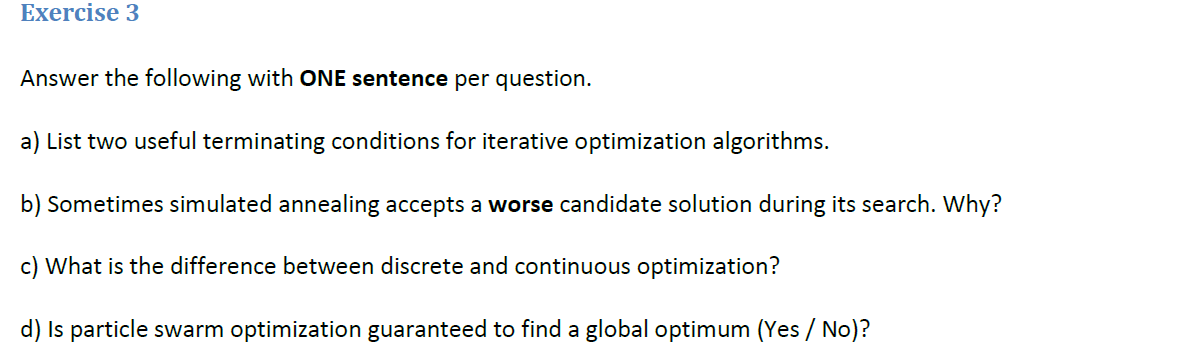

% a)
% - Accentance of error - Neuton's method could terminate when deciamals chance
% after 5 decimals. 
% - Number of interations => computation power 

% b) 
% Accepting worse solutions allows for the algorithm to explore new
% solution that may be better, and to search to the correct global optimum

% c)
% discrete optimazation uses discrete variables for the oprimazation (fixed
% data set) while continues optimazation uses continues vars such as
% continues data.

% d) No, even tho many particles form a set of candidate solutions, in some
% case the algorithm can get stuck in a local optimum.

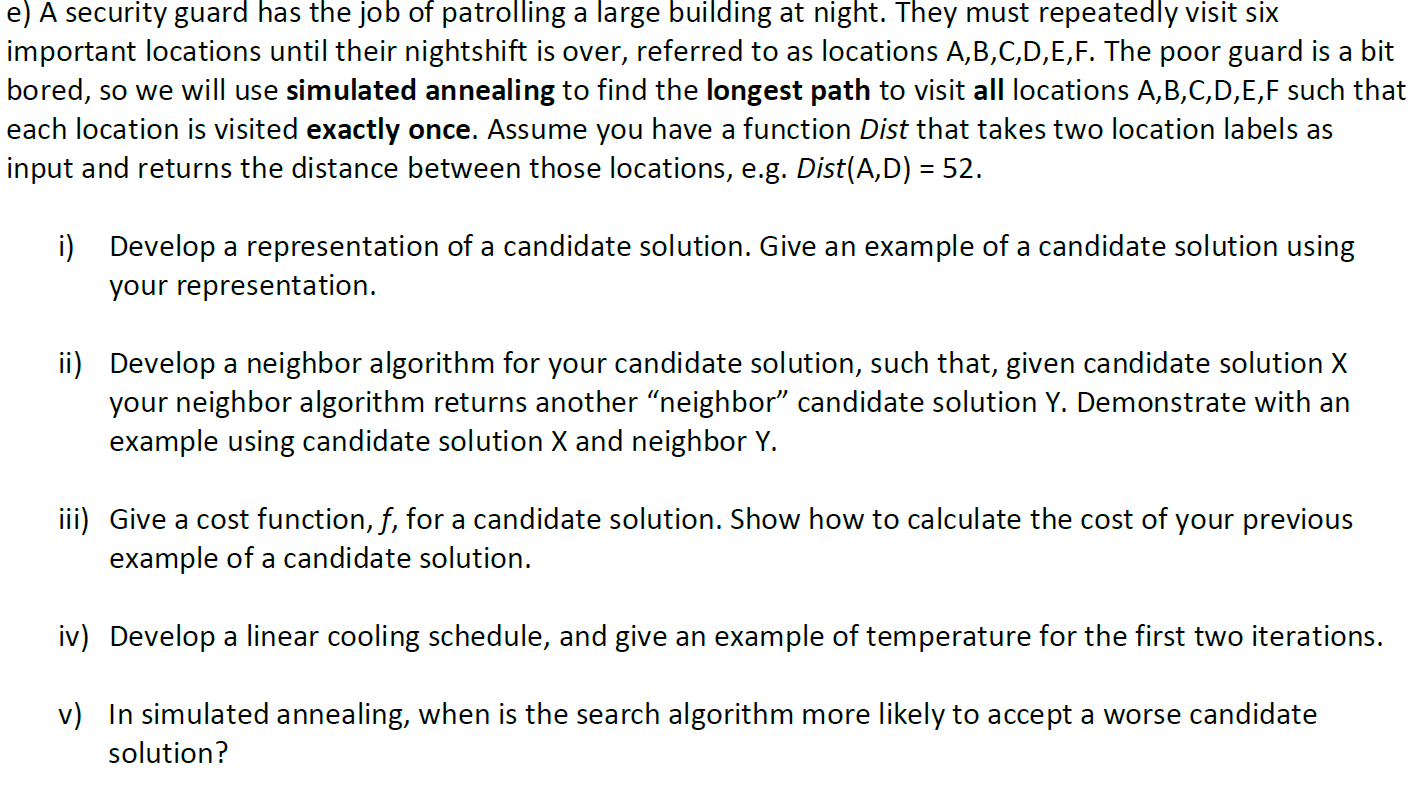

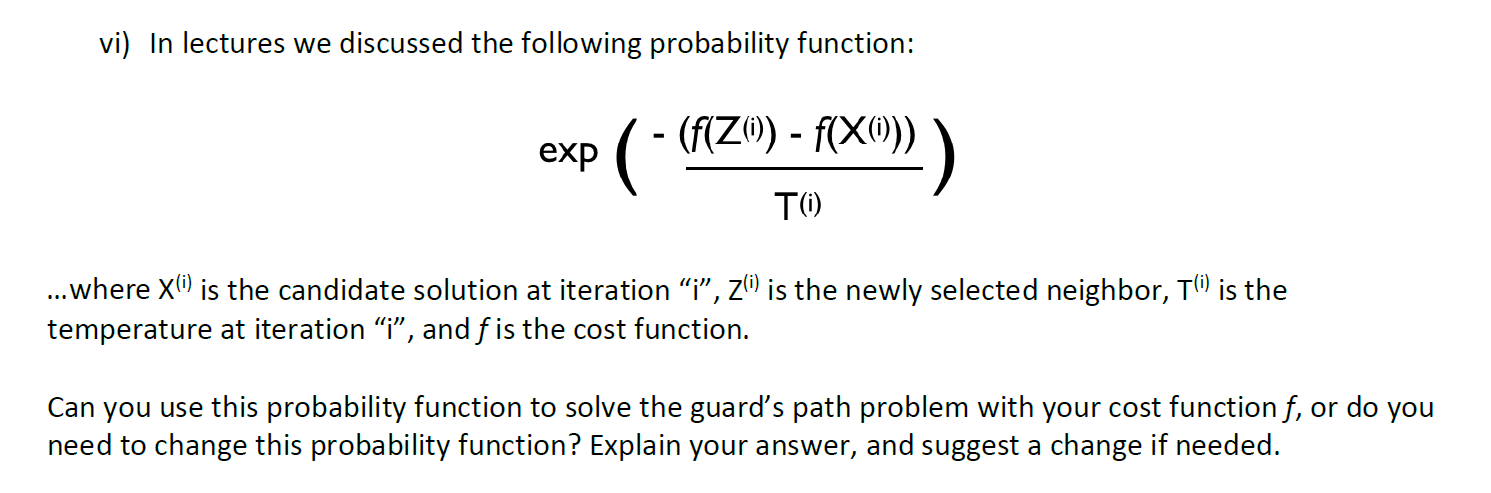

% e)
% I) 
% array of size N  --> Example : [A,B,C,D,E,F]

% II)
% We can radom select a neigbor. Then swap to obtain a second solution
% X = [A,B,C,D,E,F] --> Random select = C --> swap == Y = [C,B,A,D,E,F] 

% III) If we sum dist from start to next, then start + 1 to next +1 to the
% end.
% i is the current neighbor and N i the maximun number of neighbors. We
% call we solution set S


$$\sum_{i=1}^N \textrm{dist}\left(S\left(i\right),S\left(i+1\right)\right)$$


For given candidate example: [C,B,A,D,E,F] 

$\sum_{i=1}^N \textrm{dist}\left(S\left(i\right),S\left(i+1\right)\right)$ = dist(C,B)+ dist(C,B)+ dist(B,A)+dist(A,D)+dist(D,E)+dist(E,F)

% IV)
% Over some time i, swicth will be iteration as father we go, the higher we
% are to try worse candidate   (jump constant c = 10), t = tempature
% pr(i*t) will output c = 10 with a probabilty that is higher and higher when i and t grows 

$f\left(i,t\right)=$i*t + pr(i*t)

% V)
% When the solution is very warm. This is done so that we dont get stuck,
% and let the algorith explore new candidate soltions that may be better

% VI)
% Yes, we just have to make sure that when the function goes near 0, it has
% a higher probalitity to jump, and try out other candidates. 
% To develop at max path for the problem, the minus should be flipped in
% the function.

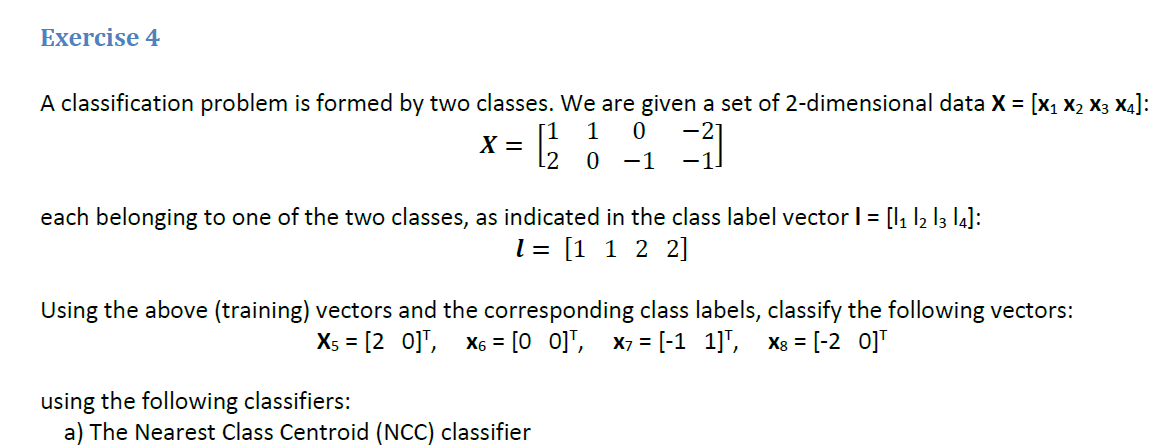


% traning data
X = [1,   1,   0,  -2;
     2,   0,  -1,  -1];

% traning labels:
l = [1,  1,  2,  2];

% testing data  
X_5 = transpose([ 2,   0]);
X_6 = transpose([ 0,   0]);
X_7 = transpose([-1,   1]);
X_8 = transpose([ 2,   0]);

for x = 5.000 dist_to_centroid1 < dist_to_centroid2 : 0.000 < 2.000  -->  we choose class 1

for x = 6.000 dist_to_centroid1 == dist_to_centroid2 : 1.000 == 1.000  -->  we just choose class 2

for x = 7.000 dist_to_centroid1 == dist_to_centroid2 : 1.000 == 1.000  -->  we just choose class 2

for x = 8.000 dist_to_centroid1 < dist_to_centroid2 : 0.000 < 2.000  -->  we choose class 1

I did the following in python. Th steps are as follows:

% Calculate the centroid for each class --> mean each x_i of each class
% Calculate the dist from test sample to each centroid
% Classify by taking the smallest dist to centroid.
% The python code can be seen as follows:

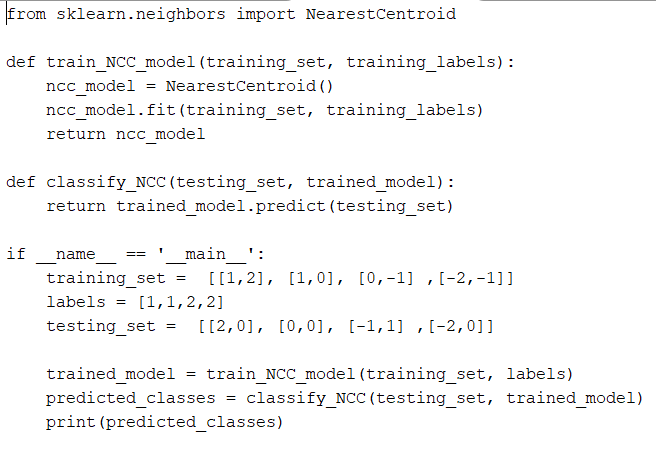

%./Nearest_Centroid      yields the prediction for [x5,x6,x7,x8] = [1 1 1 2]

% Implementation steps
% Calculate the dist to each neighbor
% Nr of neighbors == 1 --> so we ask one, which is the clooset
% The voting from the set of neighbors, in this case only 1, yeilds the
% prediction.

% The implementation is in python as follows:

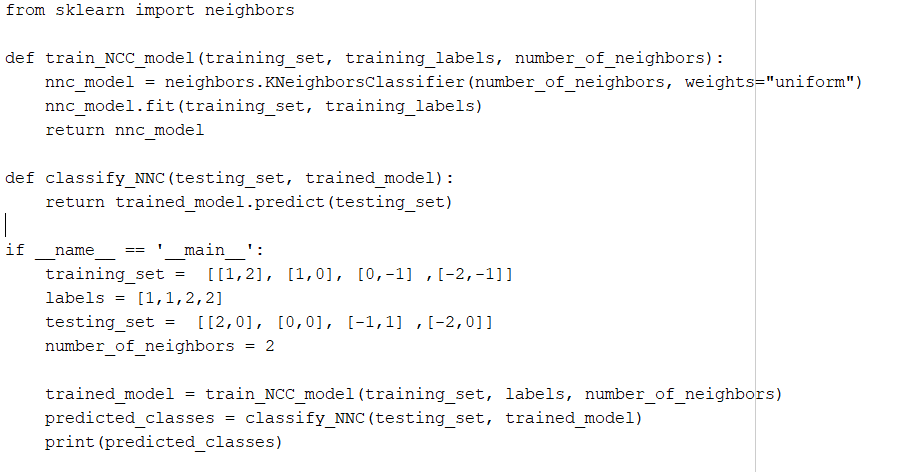

%./Nearest_Neighbor.py   yeilds the prediction for [x5,x6,x7,x8] = [1 1 1 2]

% The projection vector is calculed from different steps
% calculate the mean vector from the training set and labels
% calculate scatter matrix
% obtain the linear discriminant from largest egienvalues and egienvectors

% The following pythn code calculates the projection vector w

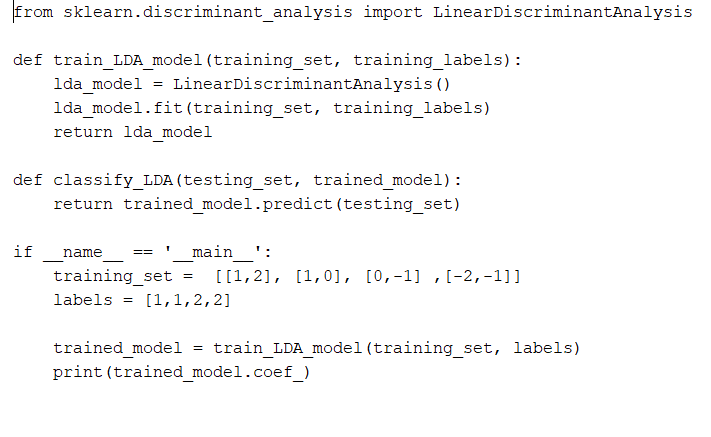

%./Nearest_Neighbor.py   yeilds the projection vector [-2, -2]

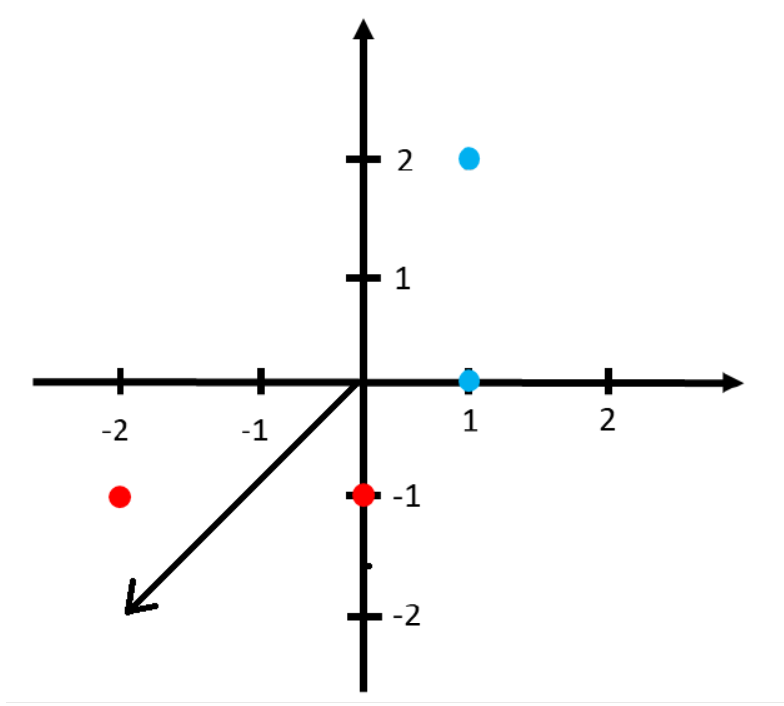

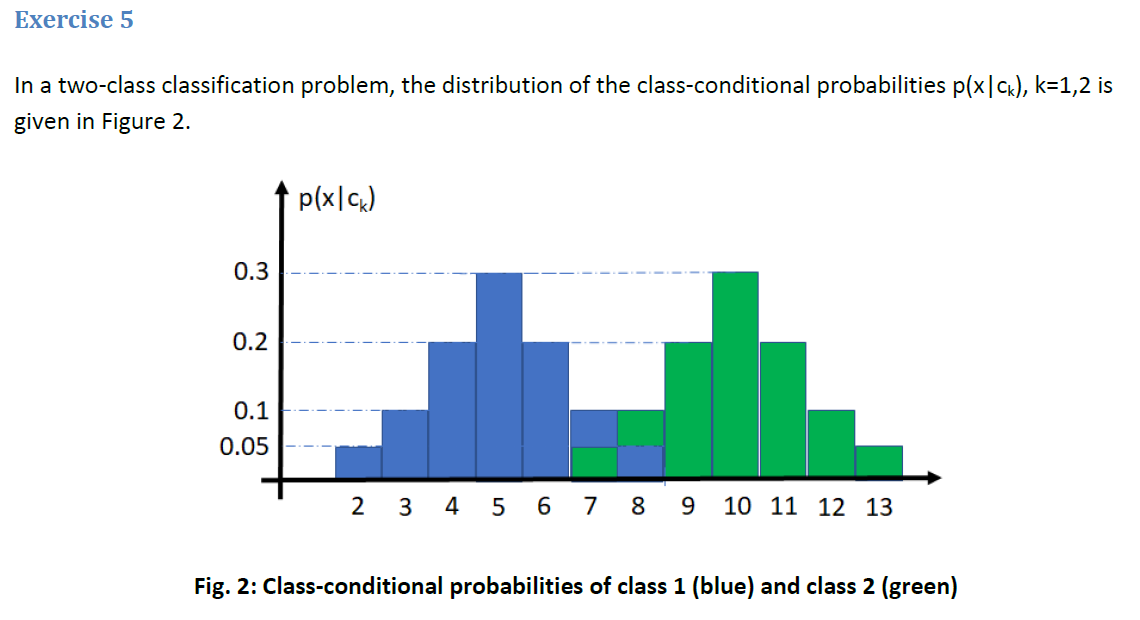

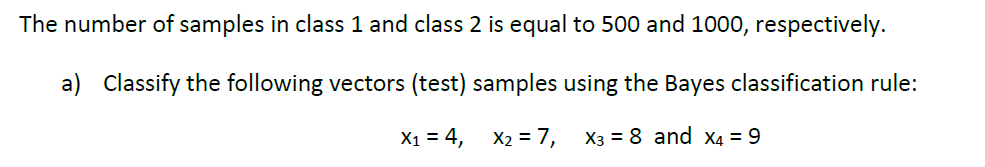

We will use the bayes formula to calculate the  $P\left(c_k \left|\;x\right.\right)$ since we alreaddy have $p\left(x\;\left|\;c_k \right.\right)$ given for every x in the trained model we can use bayers rule, to get $P\left(c_k \left|\;x\right.\right)$. Note that ine the decision function $P\left(x\right)$ gets canceled out:


$$P\left(c_k \left|x\;\right.\right)=\frac{P\left(x\left|c_k \;\right.\right)*P\left(c_k \right)}{P\left(x\right)}\;$$


We will use this decision function to decide the class:

$P\left(c_1 \left|x\;\right.\right)$> $P\left(c_2 \left|x\;\right.\right)$  

inserting from bayers we get:

 
$$\frac{P\left(x\left|c_1 \right.\right)*P\left(c_1 \right)}{P\left(x\right)}>\frac{P\left(x\left|c_2 \;\right.\right)*P\left(c_2 \right)}{P\left(x\right)}$$


Multiply by P(X), it cancels out.


$$P\left(x\left|c_1 \right.\right)*P\left(c_1 \right)>P\left(x\left|c_2 \;\right.\right)*P\left(c_2 \right)$$


% For x=4, x=7, x=8, x=9
p_x_4_given_c1 = 0.2;
p_x_4_given_c2 = 0;

p_x_7_given_c1 = 0.1;
p_x_7_given_c2 = 0.05;

p_x_8_given_c1 = 0.05;
p_x_8_given_c2 = 0.1;

p_x_9_given_c1 = 0;
p_x_9_given_c2 = 0.2;

p_c1 = 500/1500;
p_c2 = 1000/1500;

I will use the BayesTwoClassClassifer.m which i implmented for the classification.

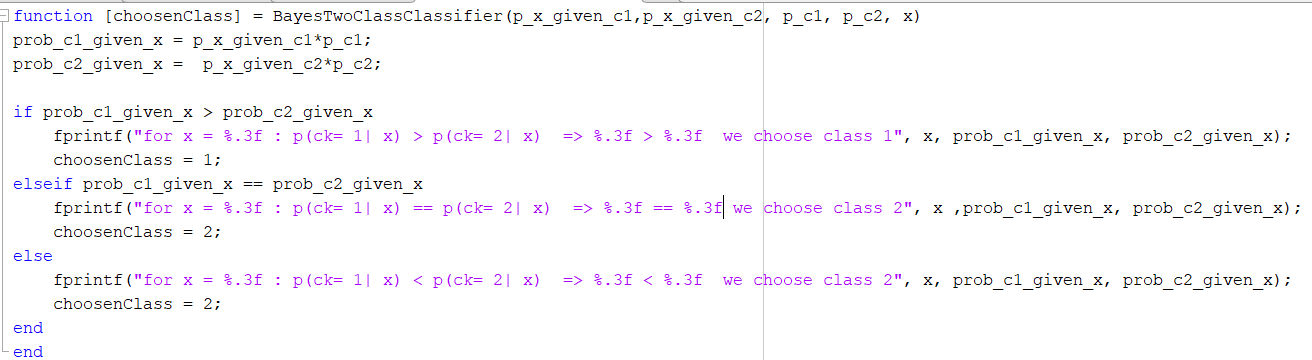

chossenClass_4 = BayesTwoClassClassifier(p_x_4_given_c1,p_x_4_given_c2,p_c1,p_c2,4);

for x = 4.000 : p(ck= 1| x) > p(ck= 2| x)  => 0.067 > 0.000  we choose class 1

chossenClass_7 = BayesTwoClassClassifier(p_x_7_given_c1,p_x_7_given_c2,p_c1,p_c2,7);

for x = 7.000 : p(ck= 1| x) == p(ck= 2| x)  => 0.033 == 0.033 we choose class 2

chossenClass_8 = BayesTwoClassClassifier(p_x_8_given_c1,p_x_8_given_c2,p_c1,p_c2,8);

for x = 8.000 : p(ck= 1| x) < p(ck= 2| x)  => 0.017 < 0.067  we choose class 2

chossenClass_9 = BayesTwoClassClassifier(p_x_9_given_c1,p_x_9_given_c2,p_c1,p_c2,9);

for x = 9.000 : p(ck= 1| x) < p(ck= 2| x)  => 0.000 < 0.133  we choose class 2

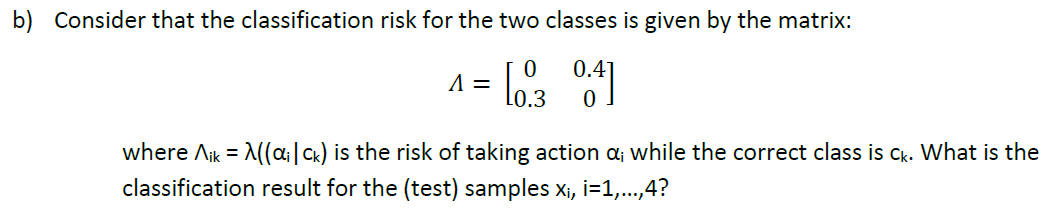

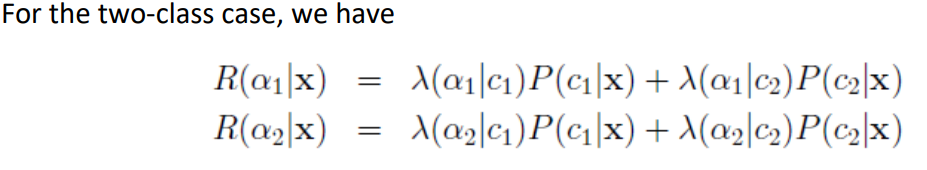

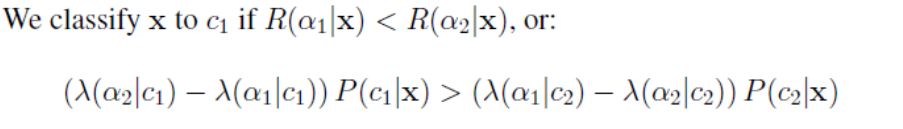

We will use the RiskClassifer.m which I implemented for the classification in matlab.

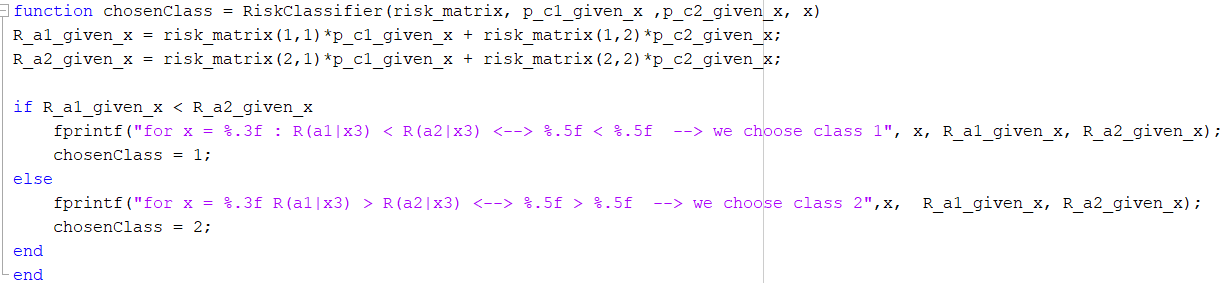

% I will assume that i = the i'th risk and for the j -> k-class
risk_matrix = [  0,  0.4;
               0.3,  0  ]

risk_matrix =          0    0.4000
    0.3000         0


% We need to calculate p(x_i) for i = 1,2,3,4 for the input value of the
% risk classifier

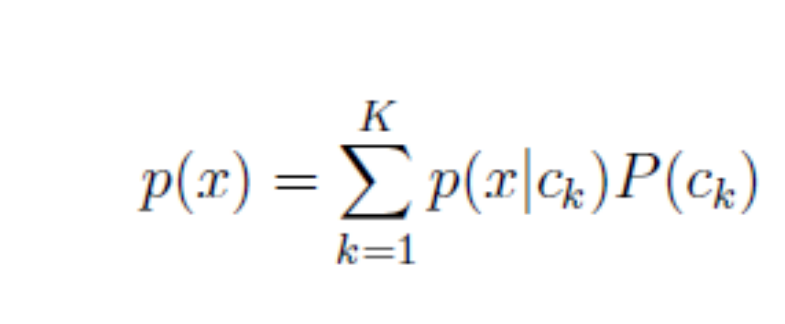

% The function for p(x) is implemented in CalcPx.m

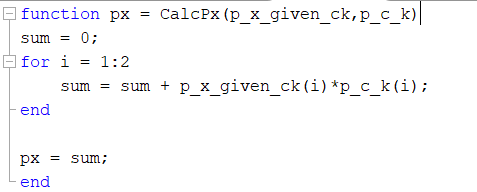

% for all
p_c_k = [p_c1, p_c2];

% x = 4
p_x4_given_ck = [p_x_4_given_c1, p_x_4_given_c2];
p_x4 = CalcPx(p_x4_given_ck,p_c_k );

% bayes
p_c1_given_x4 = (p_x_4_given_c1*p_c1)/p_x4;
p_c2_given_x4 = (p_x_4_given_c2*p_c2)/p_x4;
%classify
chosenClass_x4 = RiskClassifier(risk_matrix,p_c1_given_x4, p_c2_given_x4, 4);

for x = 4.000 : R(a1|x3) < R(a2|x3) <--> 0.00000 < 0.30000  --> we choose class 1

% x = 7
p_x7_given_ck = [p_x_7_given_c1, p_x_7_given_c2];
p_x7 = CalcPx(p_x7_given_ck,p_c_k );

% bayes
p_c1_given_x7 = (p_x_7_given_c1*p_c1)/p_x7;
p_c2_given_x7 = (p_x_7_given_c2*p_c2)/p_x7;
%classify
chosenClass_x7 = RiskClassifier(risk_matrix,p_c1_given_x7,p_c2_given_x7, 7);

for x = 7.000 R(a1|x3) > R(a2|x3) <--> 0.20000 > 0.15000  --> we choose class 2

% x = 8
p_x8_given_ck = [p_x_8_given_c1, p_x_8_given_c2];
p_x8 = CalcPx(p_x8_given_ck, p_c_k);

% bayes
p_c1_given_x8 = (p_x_8_given_c1*p_c1)/p_x8;
p_c2_given_x8 = (p_x_8_given_c2*p_c2)/p_x8;
%classify
chosenClass_x8 = RiskClassifier(risk_matrix,p_c1_given_x8,p_c2_given_x8, 8);

for x = 8.000 R(a1|x3) > R(a2|x3) <--> 0.32000 > 0.06000  --> we choose class 2

% x = 9
p_x9_given_ck = [p_x_9_given_c1, p_x_9_given_c2];
p_x9 = CalcPx(p_x9_given_ck, p_c_k);

% bayes
p_c1_given_x9 = (p_x_9_given_c1*p_c1)/p_x9;
p_c2_given_x9 = (p_x_9_given_c2*p_c2)/p_x9;
%classify
chosenClass_x9 = RiskClassifier(risk_matrix,p_c1_given_x9,p_c2_given_x9, 9);

for x = 9.000 R(a1|x3) > R(a2|x3) <--> 0.40000 > 0.00000  --> we choose class 2

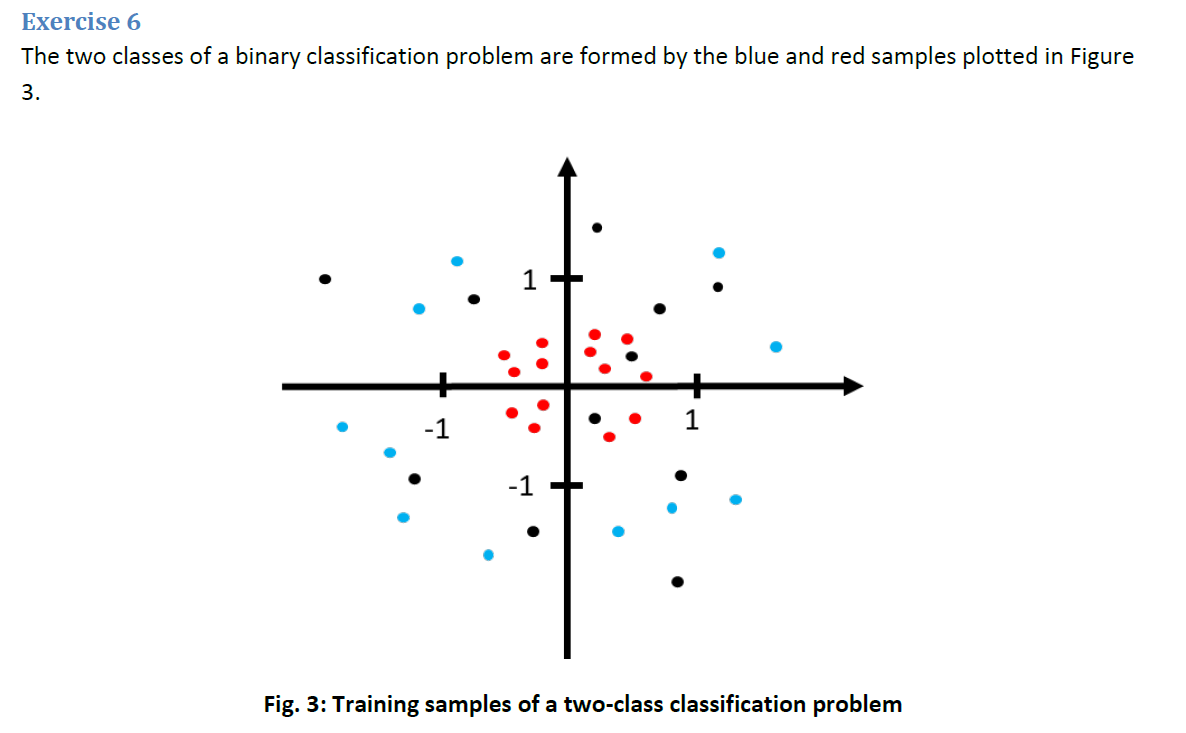

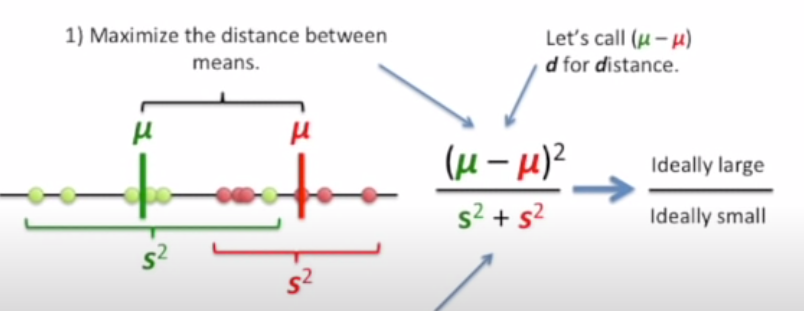

% Since the means for both classes seems very close, I whould not use LDA
% for this, since the distance between the two mean are very small swicth
% generates a bad classification between the classes. We usually want a big
% different between the means and a small scatter for both classes.
% So NO.

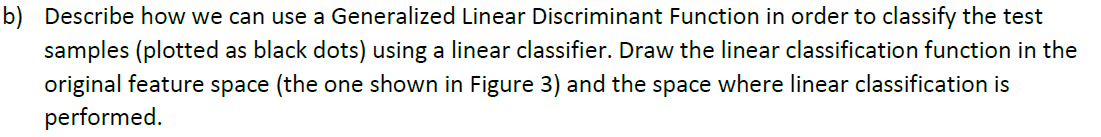

% Since the current domain is very bad for LDA, we can transform the data
% into antother domain where the mean is much better:
% f(x,y) --> f(x^2, y^2) makes a good space for the LDA
% f(x,y) --> to polar form  = R < Theta also makes a good space for LDA
% with the R values.

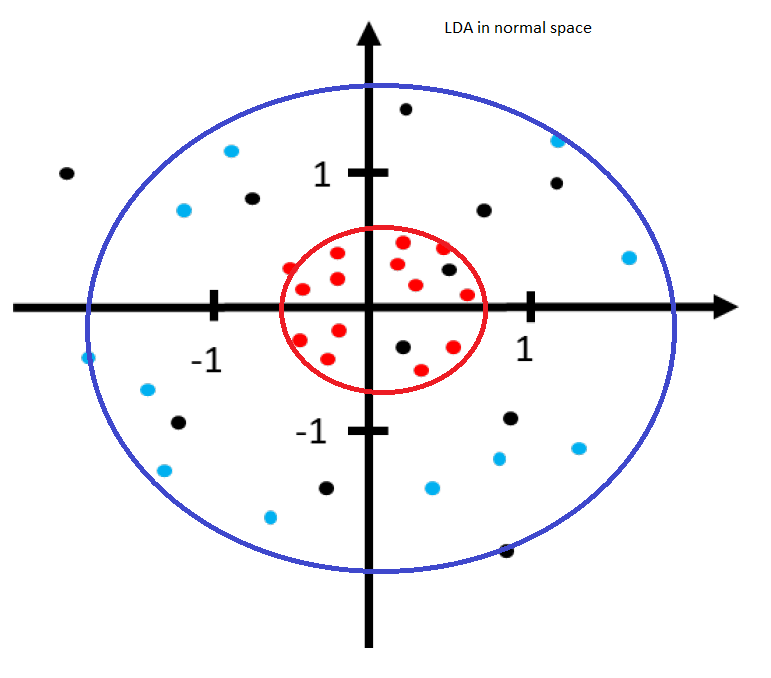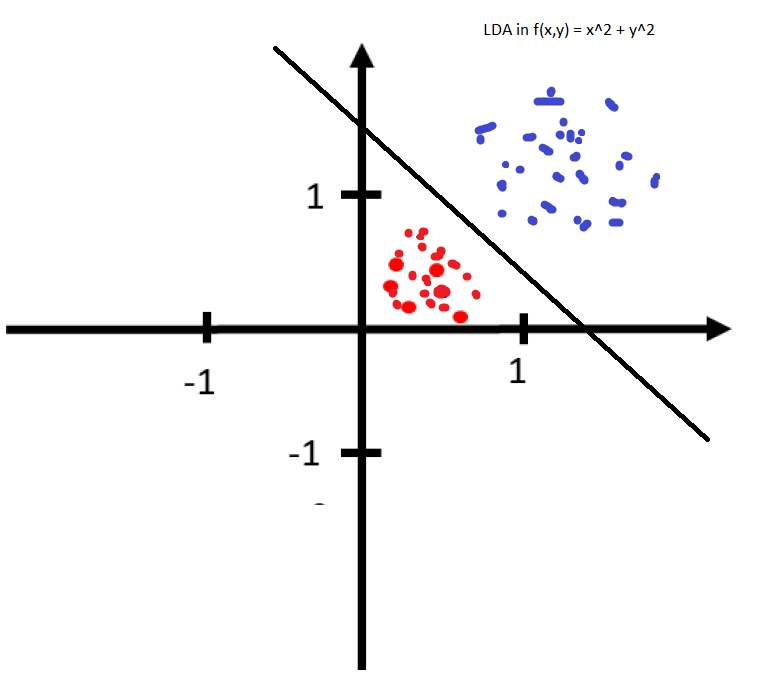

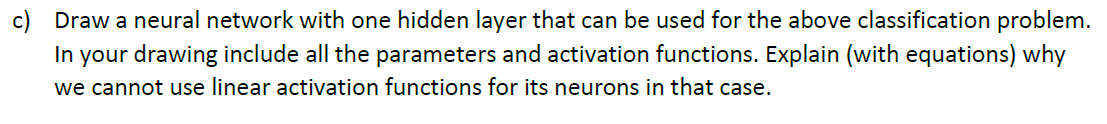

% I ) draw with http://alexlenail.me/NN-SVG/index.html
% We will have 1 hidden layer, and 2 outputs reasoned that we have 2 output
% classes. The neuron size for the hidden layer can be of any set, but it
% heavyly depends on the input problem.
% The input layer is the size of then dimension

% Input nodes are wrong ! should be number of input values   (Image of 10*10 gives 100 input)

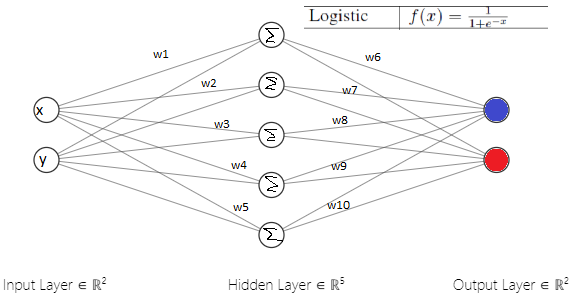

% All layers of the neural network collapse into one, because a linear
% combination of linear functions is still a linear function. Not matter
% how many hidden layers we have, the final activaition function wil just
% be a linear function of the first layer.